# **RS-WISP-07: Orbit Throwing Simulation**

**WorkerInSpace**

**Hongseok Kim**

**02/18/2025**

clear;clc;
addpath('C:\Users\user\Desktop\Redstone_WISP\RS_WISP_05_RPOD_Functions')

## I. Scope

  Orbit throwing simulation

## II. Orbit Initialization

% LEO Mode - KORSAT-1 https://www.space-track.org/basicspacedata/query/class/gp/NORAD_CAT_ID/59452/format/xml/emptyresult/show
mothership.a = 6946.773;
mothership.e = 0.00014580;
mothership.i = 45.4091;
mothership.RAAN = 235.1785;
mothership.AOP = 168.5505;
mothership.TA = 191.5406;


% GEO Mode - KOREASAT-6A https://www.space-track.org/basicspacedata/query/class/gp/NORAD_CAT_ID/61910/format/xml/emptyresult/show
% mothership.a = 42164.510;
% mothership.e = 0.00005460;
% mothership.i = 0.0172;
% mothership.RAAN = 146.3559;
% mothership.AOP = 15.8876;
% mothership.TA = 32.1826;

mu = 398600.4415;
mothership_orbit_period = 2*pi* sqrt(mothership.a^3/mu);

## III. Delta V Initialization & Orbit Propagation

note:


$$\begin{array}{l}
\textrm{From}\;\textrm{LVLH}\;\textrm{to}\;\textrm{ECI}\;\textrm{coordinate}\;\textrm{transfer},\textrm{we}\;\textrm{can}\;\textrm{calculate}\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ \;\textrm{from}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\textrm{from}\;\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_{\textrm{Mothership}} +\Omega_{\textrm{Mothership}} \times {\mathit{\mathbf{r}}}_{\textrm{rel}} +{\mathit{\mathbf{v}}}_{\textrm{rel}} \\
\;\;\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ ={\mathit{\mathbf{v}}}_{\textrm{Mothership}} +\Omega_{\textrm{Mothership}} \times \delta \mathit{\mathbf{r}}+{\left\lbrack \mathit{\mathbf{Q}}\right\rbrack }_{\textrm{LVLH},\textrm{ECI}}^{-1} \left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\;{\left\lbrack \mathit{\mathbf{Q}}\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} =\left\lbrack \begin{array}{c}
{\left(\frac{\mathit{\mathbf{r}}}{\left|\mathit{\mathbf{r}}\right|}\right)}^T \\
{\left(\frac{\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}}{\left|\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}\right|}\times \frac{\mathit{\mathbf{r}}}{\left|\mathit{\mathbf{r}}\right|}\right)}^T \\
{\left(\frac{\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}}{\left|\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}\right|}\right)}^T 
\end{array}\right\rbrack \;,\;\;\;\Omega_{\textrm{Mothership}} =\sqrt{\frac{\mu }{a^3 }}\left(\frac{\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}}{\left|\mathit{\mathbf{r}}\times \mathit{\mathbf{v}}\right|}\right)\\
\;\;\left(\textrm{note}:{\mathit{\mathbf{v}}}_0 ={\textrm{Mothership}}^{\prime } s\;\textrm{veclotiy}\;\textrm{wrt}\;\textrm{ECI},\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack ={\textrm{Object}}^{\prime } s\;\textrm{relative}\;\textrm{velocity}\;\textrm{wrt}\;{\textrm{Mothership}}^{\prime } s\;\textrm{LVLH}\right)\;\;
\end{array}$$


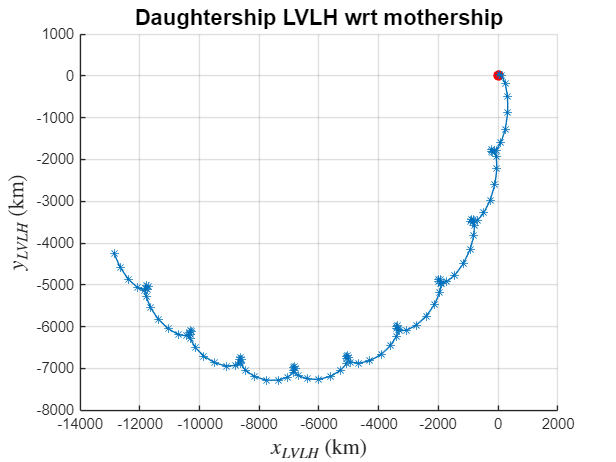

delta_v_daughtership = [0,100,0]' * 10^-3;  % Delta_v (m/s)


[r_mothership, v_mothership] = kepler2ijk_hs(mothership.a, mothership.e, mothership.i, mothership.RAAN, mothership.AOP, mothership.TA);

i = r_mothership/norm(r_mothership);
k = cross(r_mothership, v_mothership)/norm(cross(r_mothership, v_mothership));
j = cross(k,i);

Q_LVLH_ECI = [i';j';k'];

r_daughtership = r_mothership;
v_daughtership = v_mothership + inv(Q_LVLH_ECI) * delta_v_daughtership;

% v_daughtership = v_daughtership/norm(v_daughtership) * norm(v_mothership);

t_f = 10 * mothership_orbit_period;
tVec = linspace(0,t_f);
n = length(tVec);

[t,y_mothership] = orbit_propagation(r_mothership, v_mothership, tVec);
[t,y_daughtership] = orbit_propagation(r_daughtership, v_daughtership, tVec);

delta_r_lvlh_data = zeros(n,3);
delta_r_norm = zeros(n,1);

for i = 1:n

    r_eci = y_mothership(i,1:3)';
    v_eci = y_mothership(i,4:6)';

    delta_r = y_daughtership(i,1:3)' - r_eci;

    delta_r_lvlh = eci2lvlh(delta_r, r_eci, v_eci);
    delta_r_lvlh_data(i,:) =  delta_r_lvlh;
    delta_r_norm(i) = norm(delta_r);
    
end

figure;
hold on
plot3(delta_r_lvlh_data(:,1),delta_r_lvlh_data(:,2),delta_r_lvlh_data(:,3),'*-','LineWidth',0.5)
scatter3(0,0,0,50,'filled','r')
view(3)
hold off
grid on
title('Daughtership LVLH wrt mothership','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)

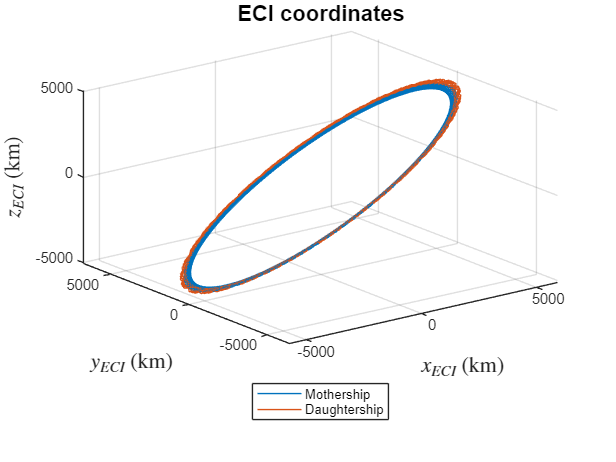


figure;
hold on
plot3(y_mothership(:,1),y_mothership(:,2),y_mothership(:,3))
view(3)
grid on
plot3(y_daughtership(:,1),y_daughtership(:,2),y_daughtership(:,3))
hold off
title('ECI coordinates','FontSize',15,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Mothership','Daughtership','Location','southoutside')

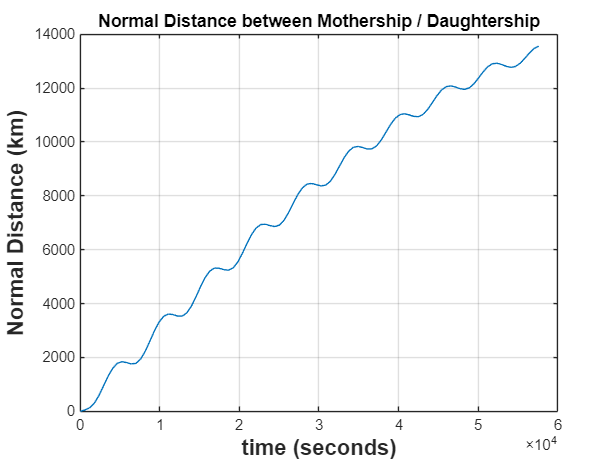


figure;
plot(t,delta_r_norm)
title('Normal Distance between Mothership / Daughtership','FontSize',12,'FontWeight','bold')
xlabel('time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('Normal Distance (km)','FontSize',15,'FontWeight','bold')
grid on

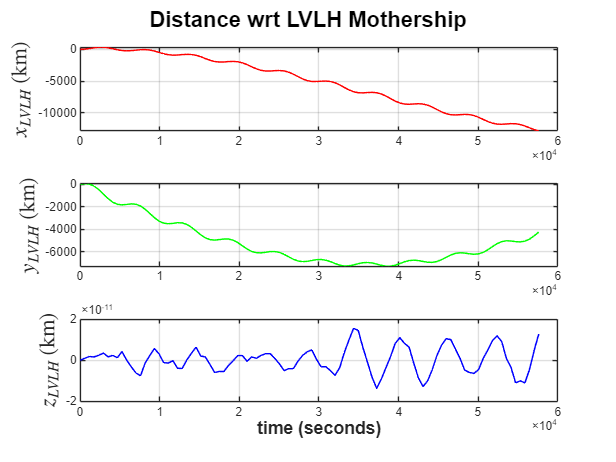


figure;
subplot(3,1,1)
plot(t,delta_r_lvlh_data(:,1),'r','LineWidth',1)
ylabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on
subplot(3,1,2)
plot(t,delta_r_lvlh_data(:,2),'g','LineWidth',1)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on
subplot(3,1,3)
plot(t,delta_r_lvlh_data(:,3),'b','LineWidth',1)
xlabel('time (seconds)','FontSize',12,'FontWeight','bold')
ylabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on
sgtitle('Distance wrt LVLH Mothership','FontSize',15,'FontWeight','bold')